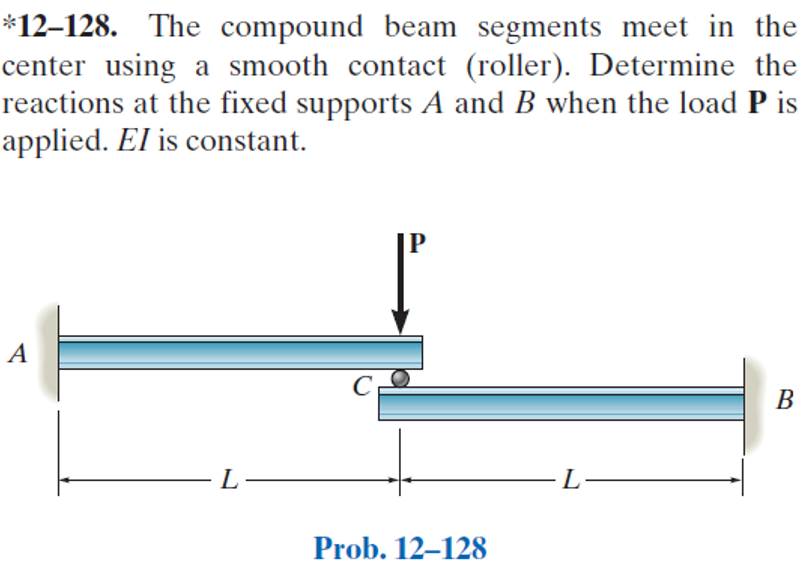

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-128P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-128P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

P = sym('P');
L = sym('L', 'positive');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('hinge', 'force', 'Hc', L);
b = b.add('concentrated', 'force', -P, L);
b = b.add('reaction', 'force', 'Rb', 2*L);
b = b.add('reaction', 'moment', 'Mb', 2*L);
b.L = 2*L;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{P\,x^{2}\,\left(3\,L-x\right)}{12\,\text{E}\,\text{I}} & \text{ if }x\leq L\\ -\frac{P\,\left(L+x\right)\,{\left(2\,L-x\right)}^{2}}{12\,\text{E}\,\text{I}} & \text{ if }L<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{P\,x\,\left(2\,L-x\right)}{4\,\text{E}\,\text{I}} & \text{ if }x\leq L\\ \frac{P\,x\,\left(2\,L-x\right)}{4\,\text{E}\,\text{I}} & \text{ if }L<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{P\,\left(L-x\right)}{2} & \text{ if }x\leq L\\ \frac{P\,\left(L-x\right)}{2} & \text{ if }L<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{P}{2} & \text{ if }x\leq L\\ -\frac{P}{2} & \text{ if }L<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & \frac{L\,P}{2}\\ \mathrm{Mb} & -\frac{L\,P}{2}\\ \mathrm{Ra} & \frac{P}{2}\\ \mathrm{Rb} & \frac{P}{2} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hc} & \frac{P}{2} \end{array}\right)$$

# shear and moment diagram

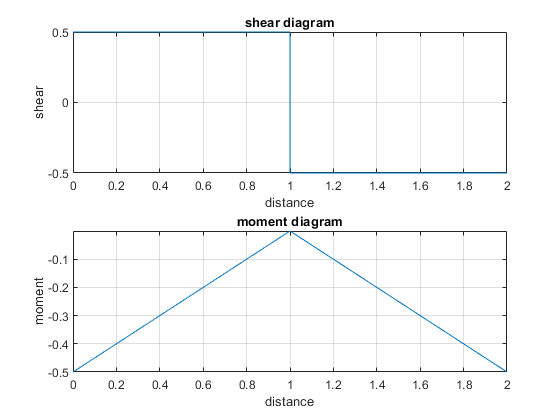

beam.shear_moment(m, v, [0 2], [P L], 1);

# clean up

addvar(y);
new_assum = assumptions;